% forcedResponsePart3 = readcell("Block 4 Data Template.xlsx", 'useExcel', true, 'Sheet', 'Part 3');

## Extract Data from 3.2: White Noise Forcing Data

freqTrial1 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 1)), 1)); % Hz
gainTrial1 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 2)), 2)); % dB
freqTrial2 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 3)), 3)); % Hz
gainTrial2 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 4)), 4)); % dB
freqTrial3 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 5)), 5)); % Hz
gainTrial3 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 6)), 6)); % dB
freqTrial4 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 7)), 7)); % Hz
gainTrial4 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 8)), 8)); % dB
freqTrial5 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 9)), 9)); % Hz
gainTrial5 = cell2mat(forcedResponsePart3(cellfun(@isnumeric, forcedResponsePart3(:, 10)), 10)); % dB

## Calculate Average for White Noise Forcing Data

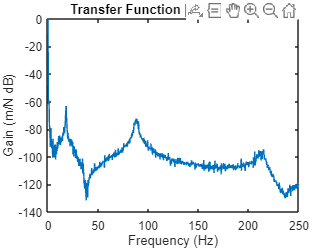

WNFD_freq = [freqTrial1 freqTrial2 freqTrial3 freqTrial4 freqTrial5];
WNFD_gain = [gainTrial1 gainTrial2 gainTrial3 gainTrial4 gainTrial5];
WNFD_freq_avg = mean(WNFD_freq, 2);
WNFD_gain_avg = mean(WNFD_gain, 2);
plot(WNFD_freq_avg, WNFD_gain_avg)
xlabel("Frequency (Hz)")
ylabel("Gain (m/N dB)")
title("Transfer Function [LDV/FT] (m/N)")